clear all;
close all;
clc;
s = tf('s');

# **Design af reguleringsmekanisme for temepratur.**

## **Åbensløjfe overføringsfunktioner.**

Der er fortaget en række målinger af varmelegemets temperaturænding af akvarievandet over tid. Disse måligner kan oversættes til en åbensløjfekaraterstid, ved antagelse om at systemet er linjært.

Målt data:

tempData = [21 23.97 25.05 25.95 26.67 27.3 27.75 28.3 28.47 28.74 29.01 29.28 29.37 29.55 29.64 29.68 29.73 29.8 29.83 29.86 29.88 29.91 29.93 29.94]

tempData =    21.0000   23.9700   25.0500   25.9500   26.6700   27.3000   27.7500   28.3000   28.4700   28.7400   29.0100   29.2800   29.3700   29.5500   29.6400   29.6800   29.7300   29.8000   29.8300   29.8600   29.8800   29.9100   29.9300   29.9400


Sampling fekvens af målinger:

fs = 1/600 %1 måling hvert 10 minutter

fs = 0.0017

plot af måling:

t_akse = ([0: 24-1])*(1/fs)

t_akse =            0         600        1200        1800        2400        3000        3600        4200        4800        5400        6000        6600        7200        7800        8400        9000        9600       10200       10800       11400       12000       12600       13200       13800


stem(t_akse, tempData, '*')
hold on

Aflæsninger fra plot

Stepresonset afsløre der er tale om et først  ordens system.

Tidskonstanten findes

tau_value=(30-21)*0.63

tau_value = 5.6700

tau = 2400

tau = 2400

Stigetid 

Stigetide = 5*tau

Stigetide = 12000

k = (30-21)/39.73 %out(ændring i grader 21->30)/input(ændring i dutycycle 0->39.73)

k = 0.2265

G = k*(1/(s*tau+1)) % Under antagelse om at det er linjærtsystme

G =
 
    0.2265
  ----------
  2400 s + 1
 
Continuous-time transfer function.



input_str = 39.73 %dutyCycle 0-40 %

input_str = 39.7300

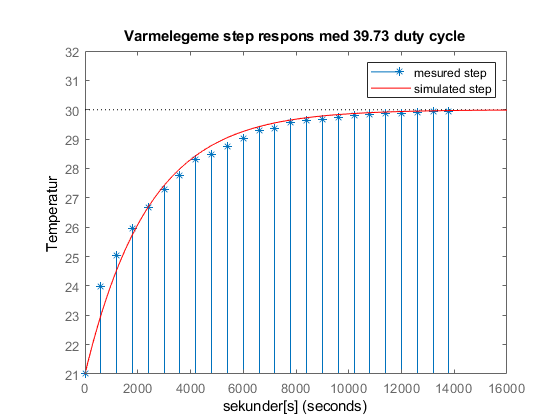

step(G*39.73+21, 'red')
title("Varmelegeme step respons med 39.73 duty cycle")
ylabel Temperatur
xlabel sekunder[s]
xlim([0 16000])
ylim([21 32])
legend('mesured step', 'simulated step')
hold off



a=1/tau

a = 4.1667e-04

k_danny=k*a

k_danny = 9.4387e-05


G_daniel=k_danny/(s+a)

G_daniel =
 
    9.439e-05
  -------------
  s + 0.0004167
 
Continuous-time transfer function.



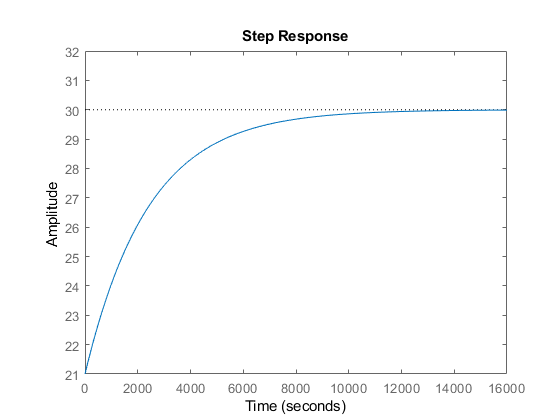

step(G_daniel*39.73+21)
xlim([0 16000])
ylim([21 32])

**Design mål**

OS < 3% (tjek krav)

sationære fejl =  0

PID modkæmpe tilføjelse af 3L vand af 21 grader.

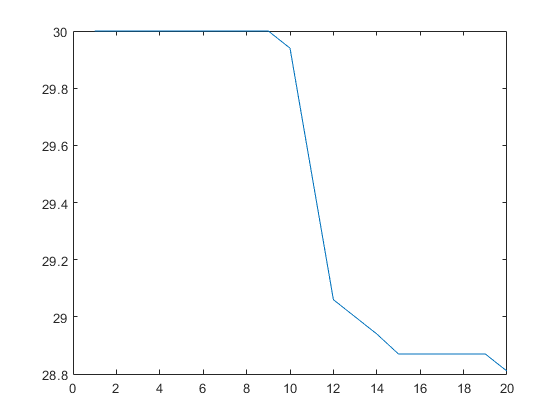

load Maling_af_30_grader_tilsat_21_grader.txt
plot(Maling_af_30_grader_tilsat_21_grader)
xlim([0 20])

margin(G)
xlim([0 10^6])

Fasemagenfrekvensen er 0.000333. burde vi lave et step for 21-22 grader istedet for?

Burde åbensløjfekarakterstikken ikke være den samme, ligegyldig hvilken størelse stepresponset vi udføre? 

f.eks:

21-22 eller 21-30 grader.

fasemagen frekven ca 2k

**Hvordan får vi den rigtige åbensløjfe-overføingsfunktion?**

**Hvad er forskellen ved at lavet et 21-22 grader step, sammelignet med et 31-30 grader?**

- Burde åbensløjfekarakterstikken ikke være den samme, ligegyldig hvilken størelse stepresponset vi udføre? 